# Assignment 7 

# Tracking in conditions of correlated biased state and measurement noise

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

## Part 1) Sensitivity of estimation results obtained by a Kalman filter that does not take into account the correlation of state noise (acceleration) and measurement noise.

**1) **Generate a true trajectory $X_i$of an object motion disturbed by a correlated in time random acceleration.

**2)** Generate measurements $Z_i$ of the coordinate $X_i$ 


$$\begin{array}{l}
a_i =e^{-\lambda T} a_{i-1} +\zeta {\;}_i \\
\eta_i =e^{-\lambda T} \eta_{i-1} +\varsigma_i \\
X_i =X_{i-1} +V_{i-1} T+a_{i-1} \frac{T^2 }{2}\\
V_i =V_{i-1} +a_{i-1} T\\
Z_i =X_i +\eta_i 
\end{array}$$


Size of trajectory is 200 points.

Initial conditions: $X_1 =5;\;V_1 =0;\lambda =1000;\;T=1-\frac{1}{\lambda };$

Variance of noise $a_{i\;} :\sigma_a^2 =0\ldotp 2^2$

Variance of noise $Z_{i\;} :\sigma_{\eta \;}^2 ={20}^2$

Variance of uncorrelated noise $\varsigma_i :\sigma_{\varsigma }^2 =\sigma_{\eta }^2 \left(1-e^{-\lambda T} \right)$

Variance of uncorrelated noise $\zeta_i :\sigma_{\zeta }^2 =\sigma_a^2 \left(1-e^{-\lambda T} \right)$

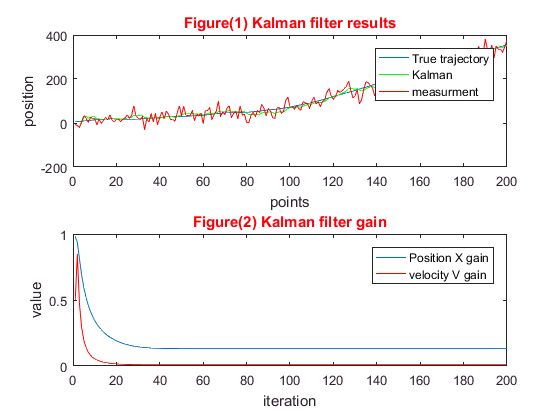

clear;
Err=zeros(500,200);            %True estimation error matrix
for M=1:500
    X=zeros(1,200);            %True trajectory
    X(1)=5;
    V=zeros(1,200);            %True velocity
    V(1)=1;
    T=1;                       %Time step
    N=length(X);               %number of points

    lambda=1000;               %inverse of correlation interval for acceleration
    elambda=exp(-lambda*T);    %constant used in the equations

    sigma_a=0.2;                                     %standard deviation of the acceleration noise
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));      %standard deviation correlated accelaration noise
    normaldist=makedist('Normal',0,sigma_zeta);      %initialization of normal distribution for random noise
    zeta=random(normaldist,200,1);                   %generation of random noise

    a=zeros(1,N);                                    %acceleration
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);                 %calculation accelartion based on noise distribution
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;           %generating the true trajectory
        V(i)=V(i-1)+a(i-1)*T;                        %generating true velocity measurements
    end
    
    lambda=1000;                                     %inverse of correlation interval for measurements noise
    elambda=exp(-lambda*T);

    sigma_eta=20;                                    %standard deviation of the measurements noise
    sigma_zeta2=sqrt((sigma_eta^2)*(1-elambda^2));   %standard deviation correlated measurements noise
    normaldist=makedist('Normal',0,sigma_zeta2);     %initialization of normal distribution for random noise
    zeta2=random(normaldist,200,1);                  %generation of random measurements noise correlated value

    eta=zeros(1,N);                                  %measurements noise initialization
    eta(1)=normrnd(0,sigma_eta);

    for i=2:N
        eta(i)=elambda*eta(i-1)+zeta2(i);            %generation of measurements noise
    end

    Z=zeros(1,200);                                  %measurements

    for i=1:N
        Z(i)=X(i)+eta(i);                            %generation of measurements
    end
    X1=X;

    %state space parameters
    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);     %iteration variable to save position values
    
    
    %initial conditions
    
    Xi=[2;0];            
    P=[10000 0; 0 10000];
    
    %initial Kalman parameters

    R=20^2;
    sigma_a=0.2^2;
    Q=G*G'*sigma_a;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,2);
    Pi=zeros(N,1);

    for i=1:2
        Xi=phi*Xi;              %prediction of X vector         
        P=phi*P*phi'+Q;         %prediction of P matrix
        Xi=Xi+K*(Z(i)-H*Xi);    %filteration and calculation new X vector
        xi(i)=Xi(1);            %storing the variables
        K=P*H'/(H*P*H'+R);      %filter gain
        Ki(i,:)=K';             %storing filter gain
        P=(eye(2)-K*H)*P;       %new P matrix value
        Pi(i)=sqrt(P(1,1));     %storing standard deviation value for estimation error
    end
    for i=3:N
        Xi=phi*Xi;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        Err(M,i)=(Xi(1)-X(i))^2;   %error calculation
     end
end
ErrAvg=zeros(1,N-2);               %Average error
%calculating average error
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

% plotting results.
figure()        
subplot(2,1,1)
plot(X)
hold on
plot(xi,'g')
plot(Z,'r')
title('Figure(1) Kalman filter results','color','r')
xlabel('points')
ylabel('position')
legend('True trajectory','Kalman','measurment')
subplot(2,1,2)
plot(Ki(:,1))
hold on
plot(Ki(:,2),'r')

title('Figure(2) Kalman filter gain','color','r')
xlabel('iteration')
ylabel('value')
legend('Position X gain','velocity V gain')

Comment: 

we created this plot of the true trajectory and the Kalman filter outputs (Error and gain) to see if everything was going as expected, with the value of $\lambda =1000$ the results were identical to what we normally get from a kalman filter with uncorolated data with the gain getting to a steady state after a short period of time and the visual comparison for the filtered data with the true trajectory. 

**3)** Obtain estimates of state vector $X=\left\lbrack \begin{array}{c}
x\\
v
\end{array}\right\rbrack$by Kalman filter over$M=500$ runs and compare true estimation errors with errors of estimation $P_{i,i}$ provided by Kalman filter algorithm.

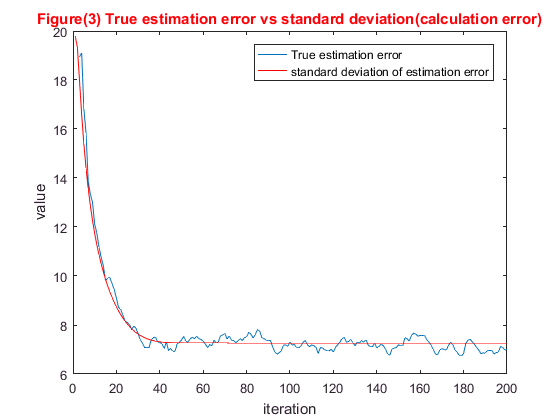

%plotting error
figure
plot(3:N,ErrAvg)
hold on
plot(Pi,'r')

title('Figure(3) True estimation error vs standard deviation(calculation error)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error')
ylabel('value')

**Comment:**

As was predicted, the behaviour of an optimal filter as with  $\lambda =1000$ the acceleration is not correlated (randomly distributed noise) with  zero mean and variance  =  $\sigma_a^2$,  the estimation error quickly reaches a steady state as the kalman gain becomes constant. The value of the error calculated by the filter is very close to the true value indicating optimal performance.

**4,5,6)** Generate trajectory and measurements again (repeat items 1 and 2), but use $\lambda =0\ldotp 1$to to generate random acceleration $a_i$. and obtain estimates of state vector $X=\left\lbrack \begin{array}{c}
x\\
v
\end{array}\right\rbrack$by Kalman filter over$M=500$ runs and compare true estimation errors with errors of estimation $P_{i,i}$ provided by Kalman filter algorithm.

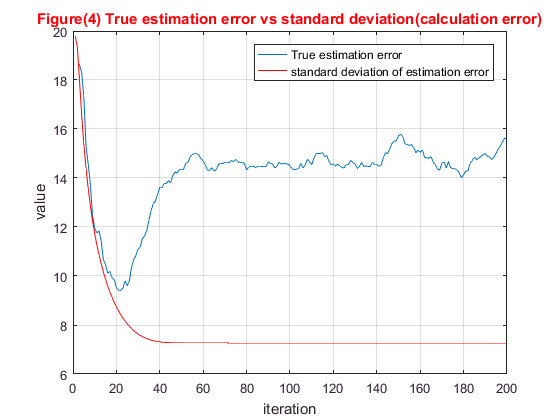

clear;
Err=zeros(500,200);            %True estimation error matrix
for M=1:500
    X=zeros(1,200);            %True trajectory
    X(1)=5;
    V=zeros(1,200);            %True velocity
    V(1)=1;
    T=1;                       %Time step
    N=length(X);               %number of points

    lambda=0.1;               %inverse of correlation interval for acceleration
    elambda=exp(-lambda*T);    %constant used in the equations

    sigma_a=0.2;                                     %standard deviation of the acceleration noise
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));      %standard deviation correlated accelaration noise
    normaldist=makedist('Normal',0,sigma_zeta);      %initialization of normal distribution for random noise
    zeta=random(normaldist,200,1);                   %generation of random noise

    a=zeros(1,N);                                    %acceleration
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);                 %calculation accelartion based on noise distribution
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;           %generating the true trajectory
        V(i)=V(i-1)+a(i-1)*T;                        %generating true velocity measurements
    end
    
    lambda=1000;                                     %inverse of correlation interval for measurements noise
    elambda=exp(-lambda*T);

    sigma_eta=20;                                    %standard deviation of the measurements noise
    sigma_zeta2=sqrt((sigma_eta^2)*(1-elambda^2));   %standard deviation correlated measurements noise
    normaldist=makedist('Normal',0,sigma_zeta2);     %initialization of normal distribution for random noise
    zeta2=random(normaldist,200,1);                  %generation of random measurements noise correlated value

    eta=zeros(1,N);                                  %measurements noise initialization
    eta(1)=normrnd(0,sigma_eta);

    for i=2:N
        eta(i)=elambda*eta(i-1)+zeta2(i);            %generation of measurements noise
    end

    Z=zeros(1,200);                                  %measurements

    for i=1:N
        Z(i)=X(i)+eta(i);                            %generation of measurements
    end
    X1=X;

    %state space parameters
    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);     %iteration variable to save position values
    
    
    %initial conditions
    
    Xi=[2;0];            
    P=[10000 0; 0 10000];
    
    %initial Kalman parameters

    R=20^2;
    sigma_a=0.2^2;
    Q=G*G'*sigma_a;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,2);
    Pi=zeros(N,1);

    for i=1:2
        Xi=phi*Xi;              %prediction of X vector         
        P=phi*P*phi'+Q;         %prediction of P matrix
        Xi=Xi+K*(Z(i)-H*Xi);    %filteration and calculation new X vector
        xi(i)=Xi(1);            %storing the variables
        K=P*H'/(H*P*H'+R);      %filter gain
        Ki(i,:)=K';             %storing filter gain
        P=(eye(2)-K*H)*P;       %new P matrix value
        Pi(i)=sqrt(P(1,1));     %storing standard deviation value for estimation error
    end
    for i=3:N
        Xi=phi*Xi;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        Err(M,i)=(Xi(1)-X(i))^2;   %error calculation
     end
end
ErrAvg=zeros(1,N-2);               %Average error
%calculating average error
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

% plotting results.
figure
plot(3:N,ErrAvg)
hold on
plot(Pi,'r')
grid on
title('Figure(4) True estimation error vs standard deviation(calculation error)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error')
ylabel('value')

**Comment:** 

In this case, our filter is non-optimal due to the wrong assumption about the state noise. the true error obviously deviating from the calculated error by the Kalman filter, both of them reaches a steady state value as the Filter gain becomes constant (Typical kalman filter behaviour). However, in case we were using real data (with no idea about the true trajectory) we will have a big problem as the results of the filter error will be much greater than what we calculated using the P matrix. So compared to an optimal filter, this one will have less filtration as we can see in figure (5) above; the value of the true estimation error is very close to the standard deviation of the measurement. 

**7,8)** Generate trajectory and measurements again (repeat items 1 and 2), but use $\lambda =1000$ to to generate random acceleration $a_i$ and $\lambda =0\ldotp 1$to generate measurements . and obtain estimates of state vector $X=\left\lbrack \begin{array}{c}
x\\
v
\end{array}\right\rbrack$by Kalman filter over$M=500$ runs and compare true estimation errors with errors of estimation $P_{i,i}$ provided by Kalman filter algorithm.

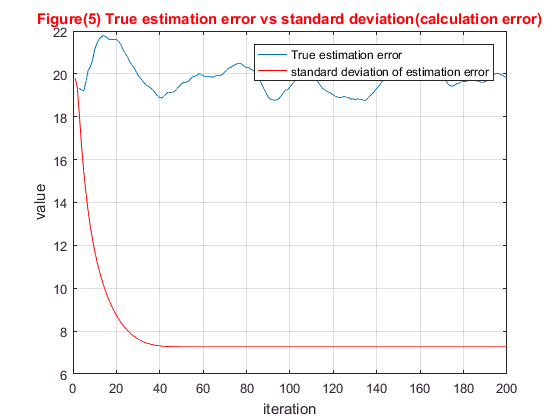

clear;
Err=zeros(500,200);            %True estimation error matrix
for M=1:500
    X=zeros(1,200);            %True trajectory
    X(1)=5;
    V=zeros(1,200);            %True velocity
    V(1)=1;
    T=1;                       %Time step
    N=length(X);               %number of points

    lambda=1000;               %inverse of correlation interval for acceleration
    elambda=exp(-lambda*T);    %constant used in the equations

    sigma_a=0.2;                                     %standard deviation of the acceleration noise
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));      %standard deviation correlated accelaration noise
    normaldist=makedist('Normal',0,sigma_zeta);      %initialization of normal distribution for random noise
    zeta=random(normaldist,200,1);                   %generation of random noise

    a=zeros(1,N);                                    %acceleration
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);                 %calculation accelartion based on noise distribution
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;           %generating the true trajectory
        V(i)=V(i-1)+a(i-1)*T;                        %generating true velocity measurements
    end
    
    lambda=0.1;                                     %inverse of correlation interval for measurements noise
    elambda=exp(-lambda*T);

    sigma_eta=20;                                    %standard deviation of the measurements noise
    sigma_zeta2=sqrt((sigma_eta^2)*(1-elambda^2));   %standard deviation correlated measurements noise
    normaldist=makedist('Normal',0,sigma_zeta2);     %initialization of normal distribution for random noise
    zeta2=random(normaldist,200,1);                  %generation of random measurements noise correlated value

    eta=zeros(1,N);                                  %measurements noise initialization
    eta(1)=normrnd(0,sigma_eta);

    for i=2:N
        eta(i)=elambda*eta(i-1)+zeta2(i);            %generation of measurements noise
    end

    Z=zeros(1,200);                                  %measurements

    for i=1:N
        Z(i)=X(i)+eta(i);                            %generation of measurements
    end
    X1=X;

    %state space parameters
    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);     %iteration variable to save position values
    
    
    %initial conditions
    
    Xi=[2;0];            
    P=[10000 0; 0 10000];
    
    %initial Kalman parameters

    R=20^2;
    sigma_a=0.2^2;
    Q=G*G'*sigma_a;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,2);
    Pi=zeros(N,1);

    for i=1:2
        Xi=phi*Xi;              %prediction of X vector         
        P=phi*P*phi'+Q;         %prediction of P matrix
        Xi=Xi+K*(Z(i)-H*Xi);    %filteration and calculation new X vector
        xi(i)=Xi(1);            %storing the variables
        K=P*H'/(H*P*H'+R);      %filter gain
        Ki(i,:)=K';             %storing filter gain
        P=(eye(2)-K*H)*P;       %new P matrix value
        Pi(i)=sqrt(P(1,1));     %storing standard deviation value for estimation error
    end
    for i=3:N
        Xi=phi*Xi;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        Err(M,i)=(Xi(1)-X(i))^2;   %error calculation
     end
end
ErrAvg=zeros(1,N-2);               %Average error
%calculating average error
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

% plotting results.
figure
plot(3:N,ErrAvg)
hold on
plot(Pi,'r')
grid on
title('Figure(5) True estimation error vs standard deviation(calculation error)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error')
ylabel('value')

**Comment:** 

Again, this isn't an optimal filter due to the wrong assumption about the measurement noise. We can see here as before a wrong estimate of error calculated by the p matrix ( crearly deviating from the true values. Also, it can be noticed that the magnitude of the true error is greater than what we got when we had the wrong assumption about the state noise which can suggest giving a bigger factor to assumptions about the measurement noise than the state noise. In other words, neglecting the correlation in measurement noise leads to greater accuracy decrease. And that the value of the error was almost constant at all points and the Kalman filter was ineffective in terms of converging to the true trajectory.

**9.** Conclude neglecting of which noise leads to greater accuracy decrease?  

Seeing from the graphs and the results obtained we can conclude that neglicting the correlatation of measurments noise has higher effect on the accuarcy and leads to higher errors and can't be depeneded on, as neglicting the correlated aceeleration error resulted to an error of almost 15 in the steady state with a difference between it and the calcualtion error of almost 8, compared to neglecting the measurments error, resulted in steady state error of 20 and the difference between it and the calculation error is almost 13. 

**10,11)** Nowenerate trajectory and measurements again (repeat items 1 and 2), but use $\lambda =0\ldotp 1$ to to generate random acceleration $a_i$ and $\lambda =0\ldotp 1$to generate measurements . and obtain estimates of state vector $X=\left\lbrack \begin{array}{c}
x\\
v
\end{array}\right\rbrack$by Kalman filter over$M=500$ runs and compare true estimation errors with errors of estimation $P_{i,i}$ provided by Kalman filter algorithm.

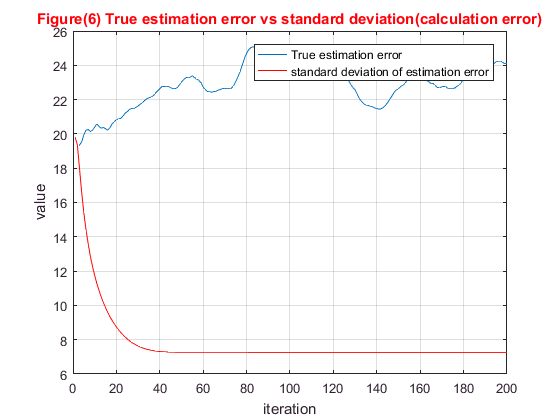

clear;
Err=zeros(500,200);            %True estimation error matrix
for M=1:500
    X=zeros(1,200);            %True trajectory
    X(1)=5;
    V=zeros(1,200);            %True velocity
    V(1)=1;
    T=1;                       %Time step
    N=length(X);               %number of points

    lambda=0.1;               %inverse of correlation interval for acceleration
    elambda=exp(-lambda*T);    %constant used in the equations

    sigma_a=0.2;                                     %standard deviation of the acceleration noise
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));      %standard deviation correlated accelaration noise
    normaldist=makedist('Normal',0,sigma_zeta);      %initialization of normal distribution for random noise
    zeta=random(normaldist,200,1);                   %generation of random noise

    a=zeros(1,N);                                    %acceleration
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);                 %calculation accelartion based on noise distribution
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;           %generating the true trajectory
        V(i)=V(i-1)+a(i-1)*T;                        %generating true velocity measurements
    end
    
    lambda=0.1;                                     %inverse of correlation interval for measurements noise
    elambda=exp(-lambda*T);

    sigma_eta=20;                                    %standard deviation of the measurements noise
    sigma_zeta2=sqrt((sigma_eta^2)*(1-elambda^2));   %standard deviation correlated measurements noise
    normaldist=makedist('Normal',0,sigma_zeta2);     %initialization of normal distribution for random noise
    zeta2=random(normaldist,200,1);                  %generation of random measurements noise correlated value

    eta=zeros(1,N);                                  %measurements noise initialization
    eta(1)=normrnd(0,sigma_eta);

    for i=2:N
        eta(i)=elambda*eta(i-1)+zeta2(i);            %generation of measurements noise
    end

    Z=zeros(1,200);                                  %measurements

    for i=1:N
        Z(i)=X(i)+eta(i);                            %generation of measurements
    end
    X1=X;

    %state space parameters
    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);     %iteration variable to save position values
    
    
    %initial conditions
    
    Xi=[2;0];            
    P=[10000 0; 0 10000];
    
    %initial Kalman parameters

    R=20^2;
    sigma_a=0.2^2;
    Q=G*G'*sigma_a;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,2);
    Pi=zeros(N,1);

    for i=1:2
        Xi=phi*Xi;              %prediction of X vector         
        P=phi*P*phi'+Q;         %prediction of P matrix
        Xi=Xi+K*(Z(i)-H*Xi);    %filteration and calculation new X vector
        xi(i)=Xi(1);            %storing the variables
        K=P*H'/(H*P*H'+R);      %filter gain
        Ki(i,:)=K';             %storing filter gain
        P=(eye(2)-K*H)*P;       %new P matrix value
        Pi(i)=sqrt(P(1,1));     %storing standard deviation value for estimation error
    end
    for i=3:N
        Xi=phi*Xi;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        Err(M,i)=(Xi(1)-X(i))^2;   %error calculation
     end
end
ErrAvg=zeros(1,N-2);               %Average error
%calculating average error
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

% plotting results.
figure
plot(3:N,ErrAvg)
hold on
plot(Pi,'r')
grid on
title('Figure(6) True estimation error vs standard deviation(calculation error)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error')
ylabel('value')

**Comment:**

Now the filter has the wrong assumptions about both the state and measurement noises, so we can use this case to assess how the non-optimal filter performed, the error in this case diverged from the true trajectory and didn't settle for an error value. which indicates how a standard Kalman filter with no robust tracking for the correlated state and measurement data fails to provide an accurate filtered data and can't be depended on. 

## Part 2) Development of optimal Kalman filter in conditions of correlated state noise.

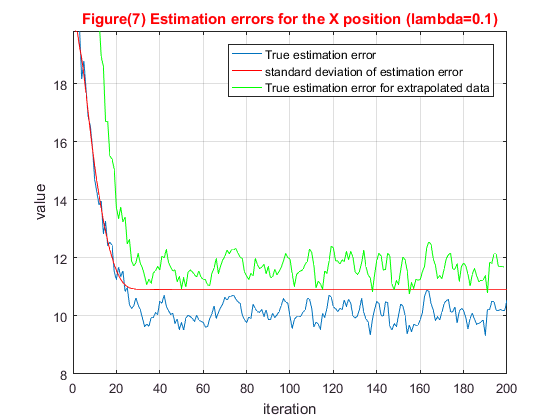

clear;
Err=zeros(500,200);         %True estimation error for X-position
ErrV=zeros(500,200);        %True estimation error for Velocity
Erra=zeros(500,200);        %True estimation error for acceleration
ErrEx=zeros(500,198);       %True estimation error for extrapolated X-position
ErrEv=zeros(500,198);       %True estimation error for extrapolated Velocity
ErrEa=zeros(500,198);       %True estimation error for extrapolated acceleration
for M=1:500
    X=zeros(1,200);
    X(1)=5;
    V=zeros(1,200);
    V(1)=1;
    T=1;
    N=length(X);

    lambda=0.1;
    elambda=exp(-lambda*T);
    elambda1=elambda;

    sigma_a=0.2;
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));
    normaldist=makedist('Normal',0,sigma_zeta);
    zeta=random(normaldist,200,1);

    a=zeros(1,N);
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;
        V(i)=V(i-1)+a(i-1)*T;
    end
    
    normaldist2=makedist('Normal',0,20);
    eta=random(normaldist2,200,1);

    Z=zeros(1,200);

    for i=1:N
        Z(i)=X(i)+eta(i);
    end
    X1=X;

    phi=[1 T T^2/2;0 1 T;0 0 elambda1];
    G=[0; 0;1];
    H=[1 0 0];

    xi=zeros(1,200);
    Xi=[2;0;0];
    P=10000*eye(3);

    R=20^2;
    sigma_a=0.2^2;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,3);
    Px=zeros(N,1);
    Pv=zeros(N,1);
    Pa=zeros(N,1);
    
    xiE=zeros(N,1);
    xx=zeros(3,1);

    for i=1:2
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(3)-K*H)*P;
        Px(i)=sqrt(P(1,1));
        Pv(i)=sqrt(P(2,2));
        Pa(i)=sqrt(P(3,3));
        XiE=Xi;
        for m=1
            XiE=phi*XiE;
            xx(:,m)=phi*XiE;
        end
        xiE(i)=XiE(1);
    end
    for i=3:N
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(3)-K*H)*P;
        Px(i)=sqrt(P(1,1));
        Pv(i)=sqrt(P(2,2));
        Pa(i)=sqrt(P(3,3));
        Err(M,i)=(Xi(1)-X(i))^2;
        ErrV(M,i)=(Xi(2)-V(i))^2;
        Erra(M,i)=(Xi(3)-a(i))^2;
        XiE=Xi;
        for m=1
            XiE=phi*XiE;
            xx(:,m)=phi*XiE;
        end
        xiE(i)=XiE(1);

        if i<N
            ErrEx(M,i)=(XiE(1)-X(i+1))^2;
            ErrEv(M,i)=(XiE(2)-V(i+1))^2;
            ErrEa(M,i)=(XiE(3)-a(i+1))^2;
        end
     end
end

%Average true estimation error calculation for X-position
ErrAvg=zeros(1,N-2);
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

%Average true estimation error calculation for extrapolated X-position
ErrAvgEx=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEx(j)=sqrt((1/(M-1))*sum(ErrEx(:,j)));
end

%Average true estimation error calculation for Velocity

ErrAvgV=zeros(1,N-2);
for j=1:N-2;
    ErrAvgV(j)=sqrt((1/(M-1))*sum(ErrV(:,j+2)));
end

%Average true estimation error calculation for extrapolated Velocity

ErrAvgEv=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEv(j)=sqrt((1/(M-1))*sum(ErrEv(:,j)));
end

%Average true estimation error calculation for acceleration

ErrAvga=zeros(1,N-2);
for j=1:N-2;
    ErrAvga(j)=sqrt((1/(M-1))*sum(Erra(:,j+2)));
end

%Average true estimation error calculation for extrapolated acceleration

ErrAvgEa=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEa(j)=sqrt((1/(M-1))*sum(ErrEa(:,j)));
end

%plotting
figure
plot(3:N,ErrAvg)
hold on
plot(Px,'r')
plot(4:(N-1),ErrAvgEx(3:end-1),'g')
title('Figure(7) Estimation errors for the X position (lambda=0.1)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')
grid on
ylim([8,max(Px)])

**Comment:**

Plotting the position estimation errors, we can see the error is less than what we got before using a non-optimal Kalman filter thus by changing the state space model to account for the noise correlation we get better results in regard of error estimation and filtration accuracy. Another thing to notice is that the calculated estimation error is higher than the true estimation error which is not a bad. Comparing the extrapolated data also can be noticed to follow the Kalman estemate with a shift in the error and if we plot the trajectory we would see them having the same pattern but with a different distances from the true trajectory. 

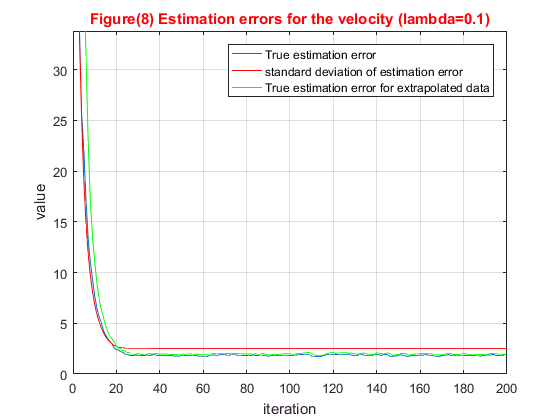

figure
plot(3:N,ErrAvgV)
hold on
plot(Pv,'r')
grid on
plot(4:(N-1),ErrAvgEv(3:end-1),'g')
grid on
title('Figure(8) Estimation errors for the velocity (lambda=0.1)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')

ylim([0,max(ErrAvgV)])

**Comment:**

Plotting the velocity estimation errors, we can see the extrapolation error and the filteration error is also similar in pattern like the position error but with a little vertical shift. Also a lower true estimation error than calculation error which is better.

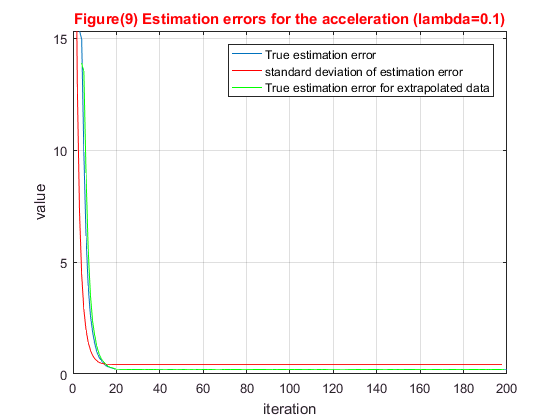

figure

plot(3:N,ErrAvga)
hold on
plot(Pa(3:end),'r')
plot(4:(N-1),ErrAvgEa(3:end-1),'g')
grid on
title('Figure(9) Estimation errors for the acceleration (lambda=0.1)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')
ylim([0,max(ErrAvga)])

**Comment:**

Plotting the accelartion estimation errors, we can see the extrapolation error and the filteration error is also similar in pattern like the position and velocity error but with a little vertical shift which is expected. Also a lower true estimation error than calculation error which is better going to zero.

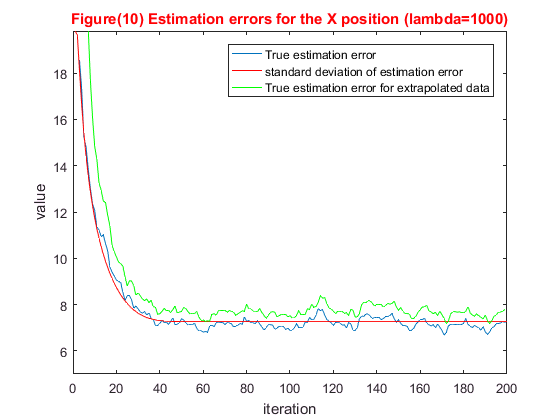

clear;
Err=zeros(500,200);         %True estimation error for X-position
ErrV=zeros(500,200);        %True estimation error for Velocity
Erra=zeros(500,200);        %True estimation error for acceleration
ErrEx=zeros(500,198);       %True estimation error for extrapolated X-position
ErrEv=zeros(500,198);       %True estimation error for extrapolated Velocity
ErrEa=zeros(500,198);       %True estimation error for extrapolated acceleration
for M=1:500
    X=zeros(1,200);
    X(1)=5;
    V=zeros(1,200);
    V(1)=1;
    T=1;
    N=length(X);

    lambda=1000;
    elambda=exp(-lambda*T);
    elambda1=elambda;

    sigma_a=0.2;
    sigma_zeta=sqrt((sigma_a^2)*(1-elambda^2));
    normaldist=makedist('Normal',0,sigma_zeta);
    zeta=random(normaldist,200,1);

    a=zeros(1,N);
    a(1)=normrnd(0,sigma_a);

    for i=2:N
        a(i)=elambda*a(i-1)+zeta(i);
    end

    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;
        V(i)=V(i-1)+a(i-1)*T;
    end
    
    normaldist2=makedist('Normal',0,20);
    eta=random(normaldist2,200,1);

    Z=zeros(1,200);

    for i=1:N
        Z(i)=X(i)+eta(i);
    end
    X1=X;

    phi=[1 T T^2/2;0 1 T;0 0 elambda1];
    G=[0; 0;1];
    H=[1 0 0];

    xi=zeros(1,200);
    Xi=[2;0;0];
    P=10000*eye(3);

    R=20^2;
    sigma_a=0.2^2;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,3);
    Px=zeros(N,1);
    Pv=zeros(N,1);
    Pa=zeros(N,1);
    
    xiE=zeros(N,1);
    xx=zeros(3,1);

    for i=1:2
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(3)-K*H)*P;
        Px(i)=sqrt(P(1,1));
        Pv(i)=sqrt(P(2,2));
        Pa(i)=sqrt(P(3,3));
        XiE=Xi;
        for m=1
            XiE=phi*XiE;
            xx(:,m)=phi*XiE;
        end
        xiE(i)=XiE(1);
    end
    for i=3:N
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(3)-K*H)*P;
        Px(i)=sqrt(P(1,1));
        Pv(i)=sqrt(P(2,2));
        Pa(i)=sqrt(P(3,3));
        Err(M,i)=(Xi(1)-X(i))^2;
        ErrV(M,i)=(Xi(2)-V(i))^2;
        Erra(M,i)=(Xi(3)-a(i))^2;
        XiE=Xi;
        for m=1
            XiE=phi*XiE;
            xx(:,m)=phi*XiE;
        end
        xiE(i)=XiE(1);

        if i<N
            ErrEx(M,i)=(XiE(1)-X(i+1))^2;
            ErrEv(M,i)=(XiE(2)-V(i+1))^2;
            ErrEa(M,i)=(XiE(3)-a(i+1))^2;
        end
     end
end

%Average true estimation error calculation for X-position
ErrAvg=zeros(1,N-2);
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end

%Average true estimation error calculation for extrapolated X-position
ErrAvgEx=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEx(j)=sqrt((1/(M-1))*sum(ErrEx(:,j)));
end

%Average true estimation error calculation for Velocity

ErrAvgV=zeros(1,N-2);
for j=1:N-2;
    ErrAvgV(j)=sqrt((1/(M-1))*sum(ErrV(:,j+2)));
end

%Average true estimation error calculation for extrapolated Velocity

ErrAvgEv=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEv(j)=sqrt((1/(M-1))*sum(ErrEv(:,j)));
end

%Average true estimation error calculation for acceleration

ErrAvga=zeros(1,N-2);
for j=1:N-2;
    ErrAvga(j)=sqrt((1/(M-1))*sum(Erra(:,j+2)));
end

%Average true estimation error calculation for extrapolated acceleration

ErrAvgEa=zeros(1,N-1);
for j=1:N-2;
    ErrAvgEa(j)=sqrt((1/(M-1))*sum(ErrEa(:,j)));
end

%plotting
figure
plot(3:N,ErrAvg)
hold on
plot(Px,'r')
plot(4:(N-1),ErrAvgEx(3:end-1),'g')
title('Figure(10) Estimation errors for the X position (lambda=1000)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')
ylim([5,max(Px)])

**Comment:**

Now with uncorrelated noise for both the measurments and states, the calculation error and the true estimation error coincide and have almost the same steady state value with the same rate of convergence. but for the extrapolation the same behaviour appeared like the correlated noise case with the extraploated data have similar trend but shifted.

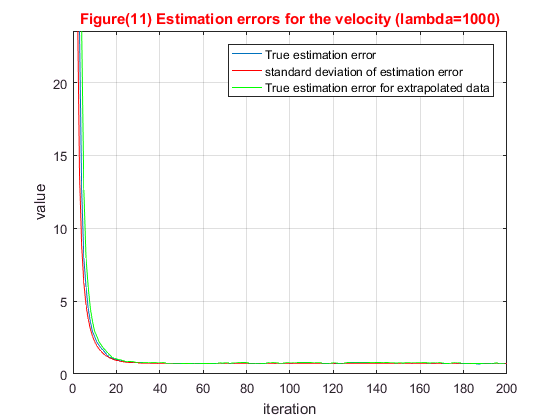

figure
plot(3:N,ErrAvgV)
hold on
plot(Pv,'r')
grid on
plot(4:(N-1),ErrAvgEv(3:end-1),'g')
grid on
title('Figure(11) Estimation errors for the velocity (lambda=1000)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')

ylim([0,max(ErrAvgV)])

**Comment:**

Plotting the velocity estimation errors, we can see the extrapolation error and the filteration error conincide together with a little shift and coinciding with calculation error and converging to a value close to zeros.

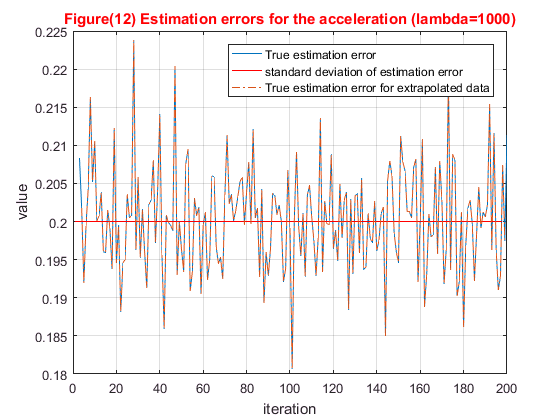

figure

plot(3:N,ErrAvga)
hold on
plot(Pa(3:end),'r')
plot(4:(N-1),ErrAvgEa(3:end-1),'-.')
grid on
title('Figure(12) Estimation errors for the acceleration (lambda=1000)','color','r')
xlabel('iteration')
legend('True estimation error','standard deviation of estimation error','True estimation error for extrapolated data')
ylabel('value')

**Comment:**

Plotting the acceleration estimation errors, we can see the extrapolation error and the filteration error conincide together with no shift here and that they are both similar but they oscilate around the calculation error with small diffetence of +/- 0.01 which is a very fine result to depend on.

**General conclusion:**

Using the modified kalman filter algorithm gave a better results for correlated cases, and yet the same results for the uncorrelated noise compared to the standard Kalman filter, which means we can rely on it for better filteration of differnet sets of data, because it contains a tracking algorithm for tracking correlations whether they exist or not. And that in cases of using standard Kalman filter with correlated noises it might result in big errors and sometimes divergence.

# Learning Log:

Well, by studying many cases in this assignment, we have learned more about the Kalman filter, using different variations of both our system and the filter itself; which gave us a wholesome of the practical sense to conduct analysis with different versions of Kalman filter. Specifically, we have learned how the ordinary Kalman filter can't account for the correlation in state and measurment noises. For that, we modified it a little bit to take this correlation into consideration. And if we conclude some points and to reflect on our learning:

1- Standard Kalman filter is ineffective and inaccurate in cases of correlated state or measurement noise, so for a robust calculation of true trajectories a tracking algorithm like which we developed is better to use and gives higher accuracy in most cases.

2- Kalman filter variations throughout this assignment and the one preceeding it never fail to show us that it's senstive to input data and conditions.

3- To use Kalman filter in practical conditions we need to know ecxactly what we are modeling and what can tackle our problem because of the sensitivity problem.

4- Kalman filter can diverge from the true trajectory which we haven't seen earlier, Hence, we need to verify the results after we obtain them with experimenting for practical cases.